# **Practice 10b: Data acquisition with square velocity input**

[https://tsc-lab.blogspot.com/2021/06/practice-10-data-acquisition-with.html](https://tsc-lab.blogspot.com/2021/06/practice-10-data-acquisition-with.html)

- **Blog: **[**https://tsc-lab.blogspot.com/**](https://tsc-lab.blogspot.com/)

- **GitHub: **[**https://github.com/vasanza/TSC-Lab**](https://github.com/vasanza/TSC-Lab)

- **Matlab functions: **[**https://github.com/vasanza/Matlab_Code**](https://github.com/vasanza/Matlab_Code)

- `IEEEDataPort: `[**http://ieee-dataport.org/4138**](http://ieee-dataport.org/4138)

- `TSC-LAB configurations`

- `int dutyCycleInitial = 255;`

- `int dutyCycleFinish = 0;`

- `int period = 13000;`

- `int cycles = 50;`

- `1 sample per second`

# Raw dataset preparation

clear;clc;%clear all
addpath(genpath('./src'))%functions folders
datapath = fullfile('./data/');%data folder

# Raw dataset preprocessing

filenames = FindCSV(datapath);%List All CSV files
data=readtable(fullfile(datapath,filenames(1).name));%Select i CSV file
data=table2array(data);
DataNorm = fNormalization(data(:,1));%Normalization
DataFeatures = [max(DataNorm) min(DataNorm) mean(DataNorm)...
    median(DataNorm) rms(DataNorm) std(DataNorm) ];%Feature extraction

# Plot Raw TSC-LAB dataset

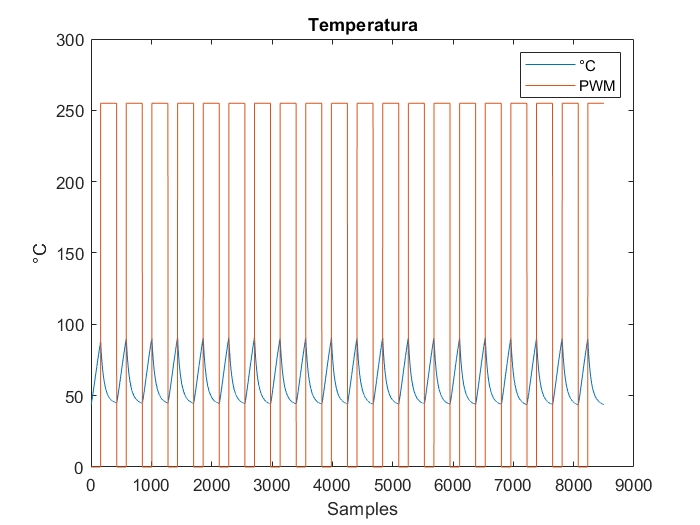

figure
plot(data);xlabel('Samples');ylabel('°C');
title('Temperatura');
legend('°C','PWM');

# Plot Normalization dataset

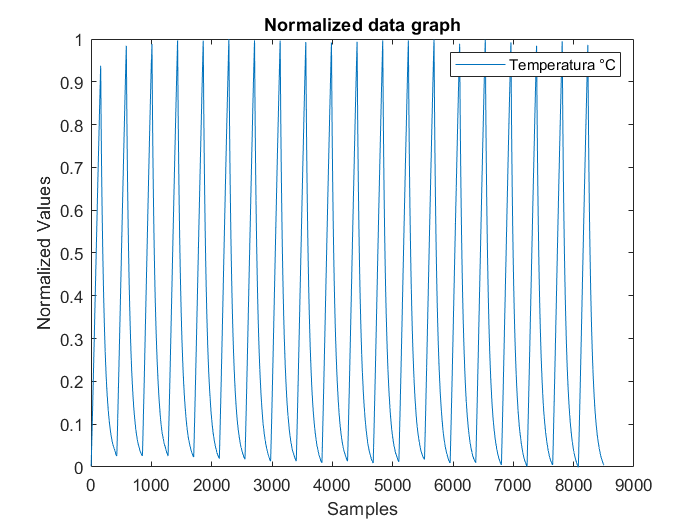

figure
plot(DataNorm);xlabel('Samples');ylabel('Normalized Values');
title('Normalized data graph');
legend('Temperatura °C');

# Select a case

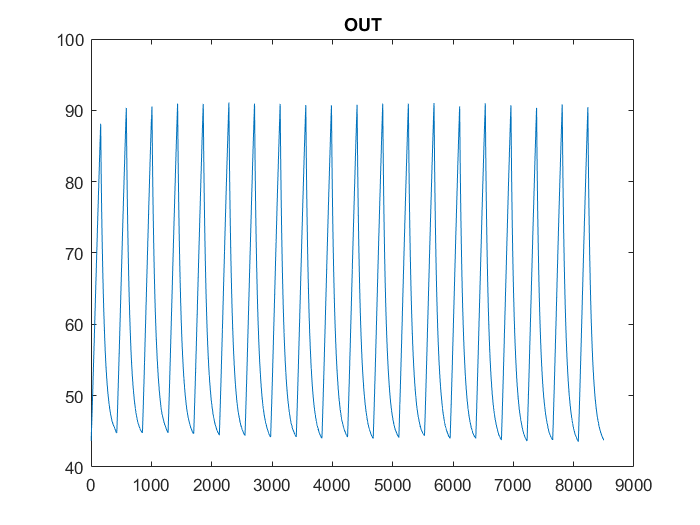

IN=data(:,end);%Temperatura
OUT=data(:,1);%PWM
figure
plot(OUT)
title('OUT');

# System Identification

systemIdentification

'systemIdentification' requires System Identification Toolbox.

**Select Range**

- **70% Training**

- **30% Validation**

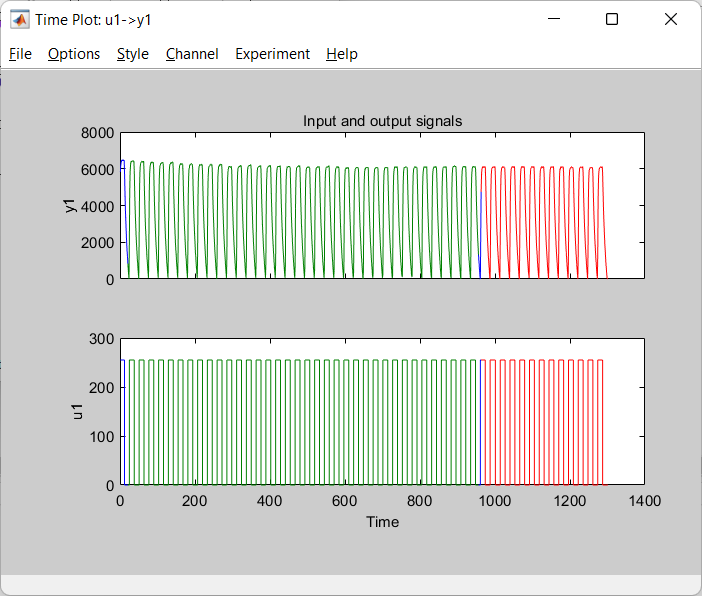

# **Practica 15: Estimate (3 metodos)**

# [https://tsc-lab.blogspot.com/2021/11/practice-15-system-3-using-motor.html](https://tsc-lab.blogspot.com/2021/11/practice-15-system-3-using-motor.html)

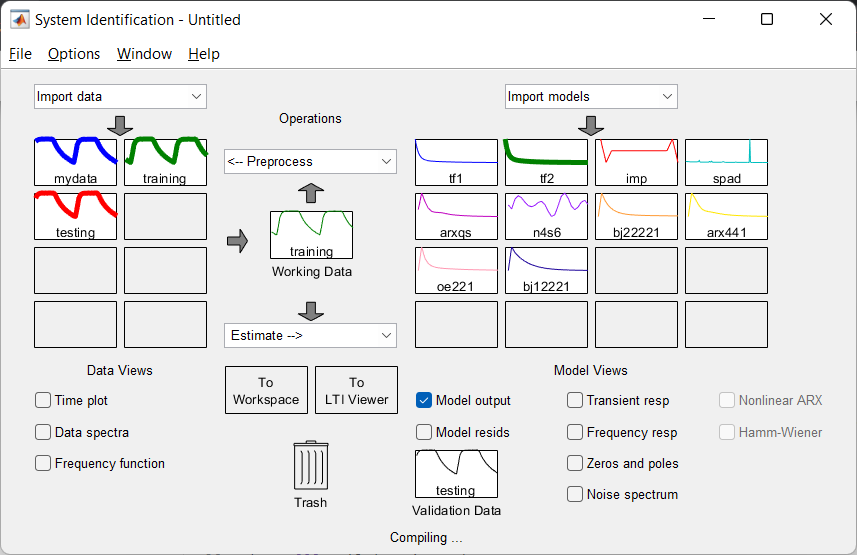

**Comparamos el modelo con el mejor FIT y lo enviamos a WorkSpace**

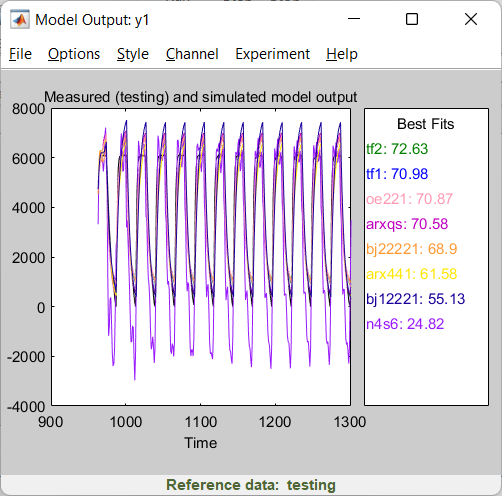

# `Función de Transferencia obtenida (Metodo 3)`

%% Función de Transferencia obtenida (Metodo 3)
%G=tf(d2c(tf2));%<---Modelo con mejor FIT
G=tf(tf2);%<---Modelo con mejor FIT

Unrecognized function or variable 'tf2'.

num=cell2mat(G.numerator);
den=cell2mat(G.denominator);
FTmotor=tf(num,den)

Time=(0:1:length(IN)-1)'; %Vector de tiempo
y = lsim(G,IN,Time); % system response
figure(1)
plot(y);
hold on;
plot(IN);
plot(OUT);
legend('Estimate','Input','Output');

# `Simulink`

# [`https://drive.google.com/drive/folders/1MhowqEwFYbOfjSBX1NyZB3ZDA1uJEgBi`](https://drive.google.com/drive/folders/1MhowqEwFYbOfjSBX1NyZB3ZDA1uJEgBi)

## `NOTA: Cargar el codigo en el TSC-LAB `

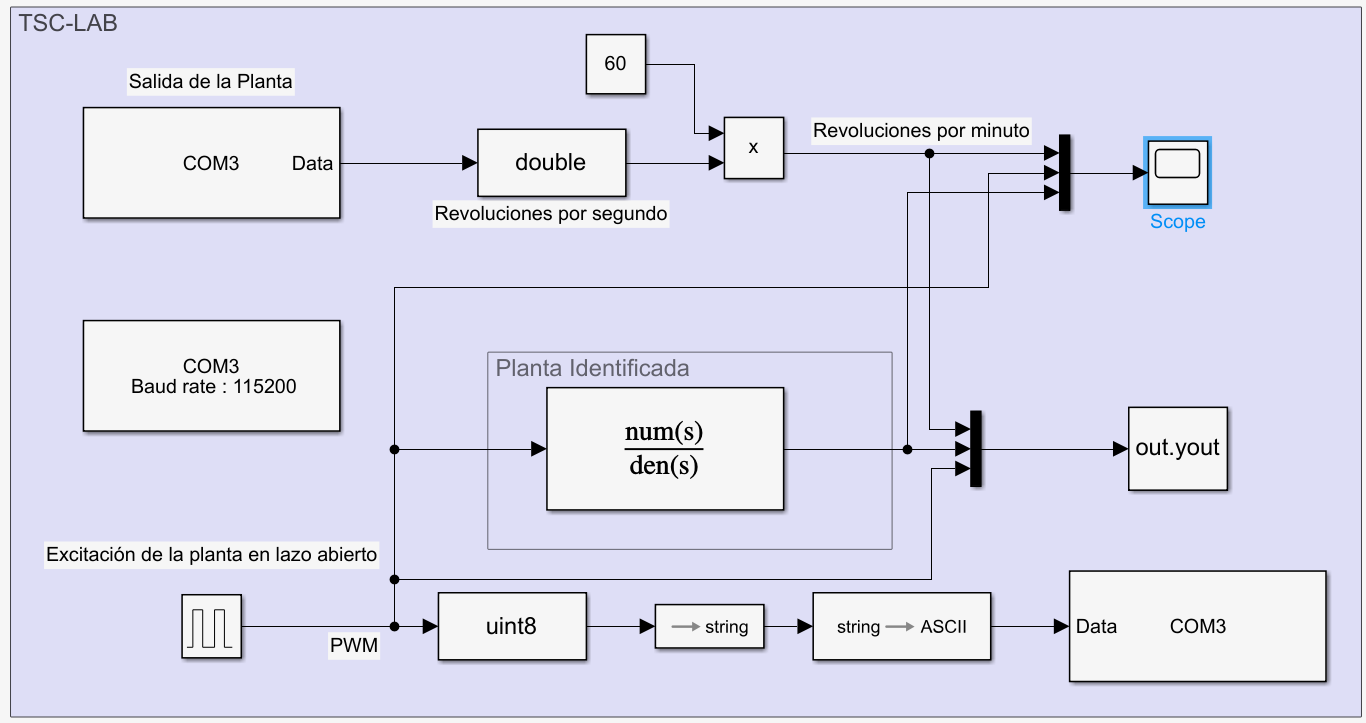

## En el Serial Send adicionar la temrinación en "/n"

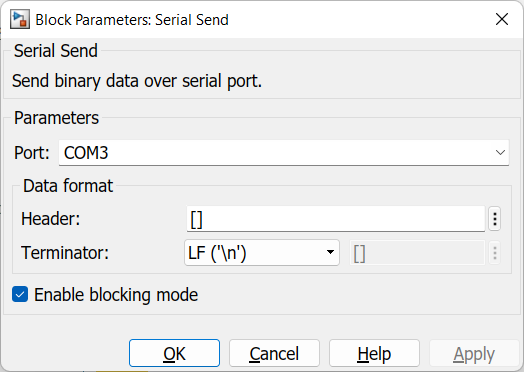

## Escribir la ecuacion identificada en Transfer Fcn:

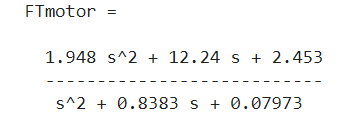

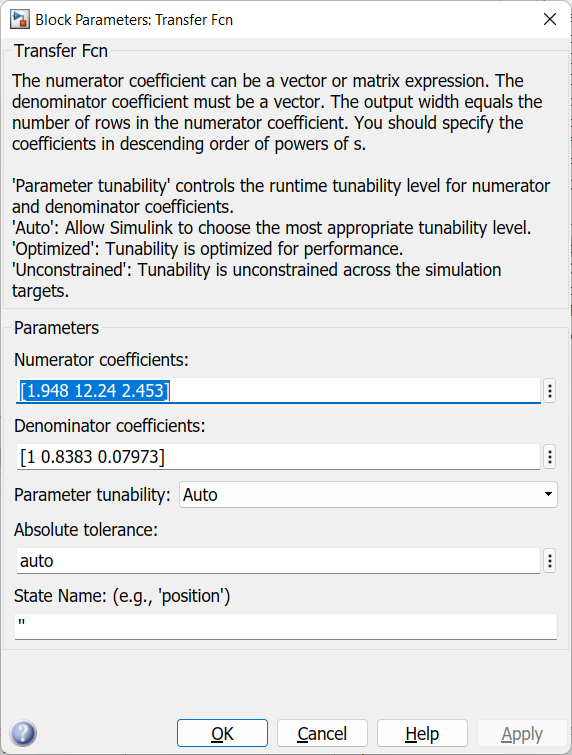

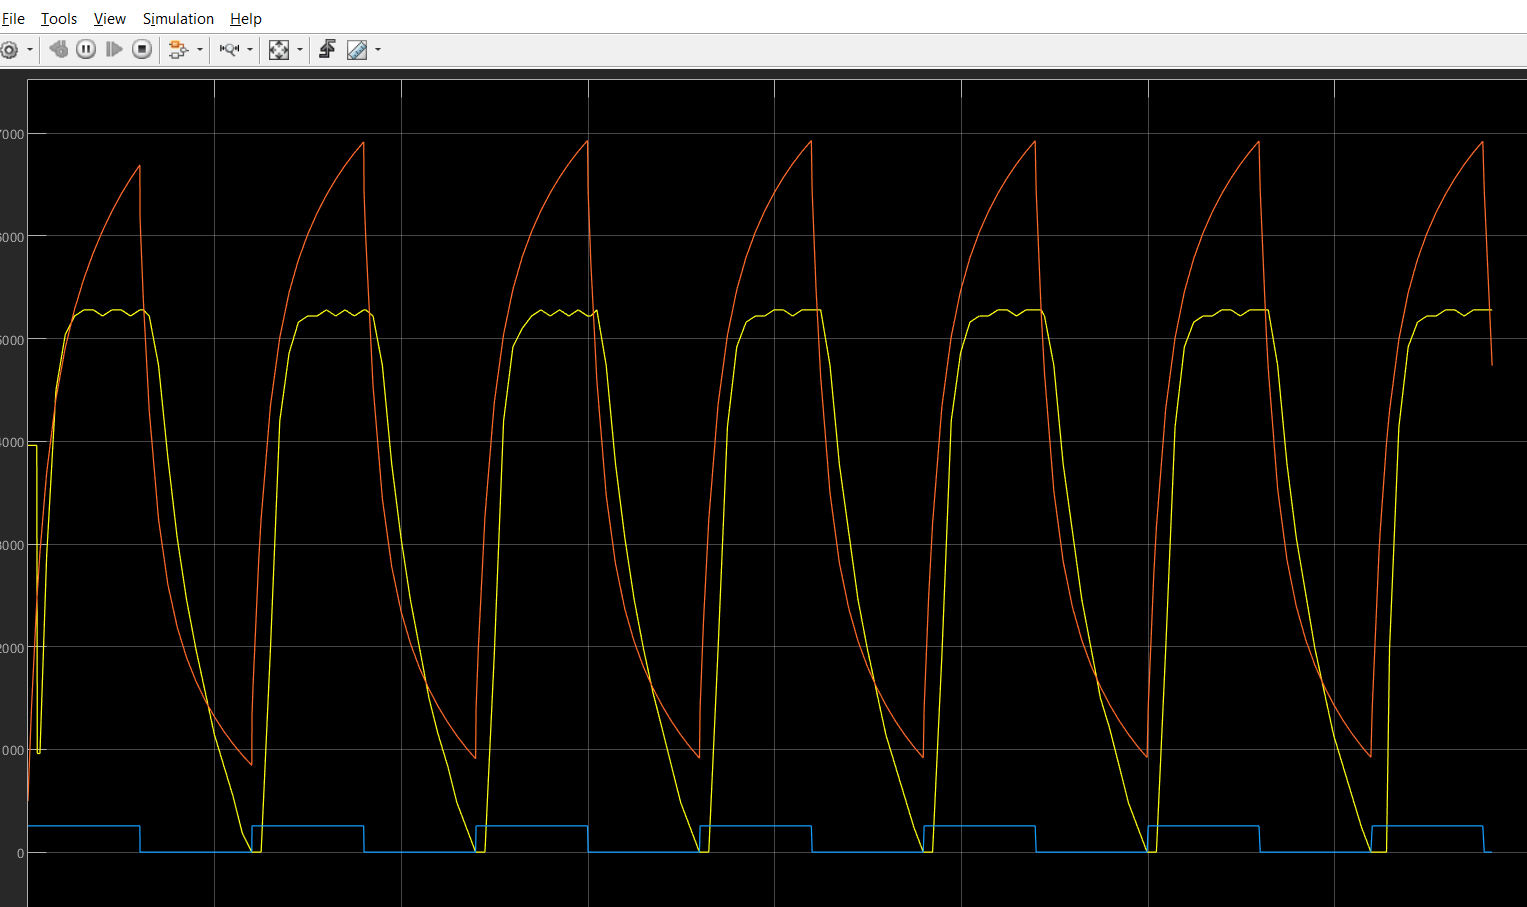

# `Graficar datos enviados a WorkSpace desde Simulink`

PlantaRPM=out.yout(:,1);
ModeloRPM=out.yout(:,2);
Step=out.yout(:,3);

plot(PlantaRPM)
hold on
plot(ModeloRPM)
plot(Step)
title("Comparación modelo Planta y Modelo");
xlabel("Samples");
ylabel("RPM");
legend('Planta','Modelo','Step');
grid on

# TAREA

- **Con la planta modificada de su pproyecto, encontrar el mejor modelo de identificación.**

- **Con  ese mejor modelo se realizará el controlador.**